# 3. Fourier Series

## 3.1 Basics

## 3.4 Complex form of Fourier series

## 3.5 Spectra

####    Example: Fourier coefficient of even square wave. Let’s plot it.

## 3.6 Effect of time window

## 3.1 Basics

Periodic signals can be expressed by sine or cosine function:

where w is angular freq. (rad/s), f is freq. (Hz). Period is Tp = 1/f = 2pi/w seconds.

For arbitrary periodic signal, the function is given by

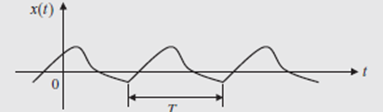  

where fundamental freq. is f1 = 1/Tp, and all other freq's are multiples of this.

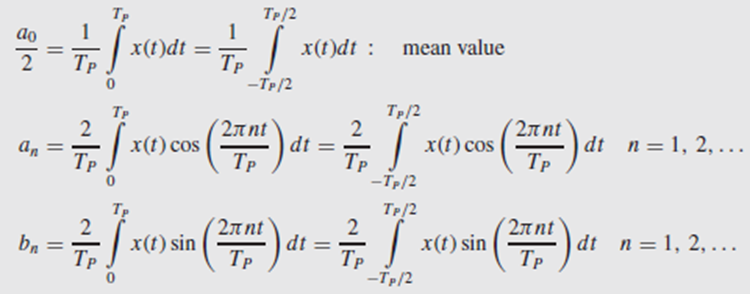

a0/2 is the DC level or mean of the signal. This can be expressed differently as

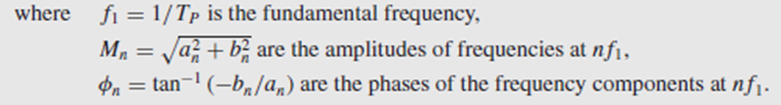

So what we determine is (an, bn) or (Mn, phi_n).

**Example - odd square wave **

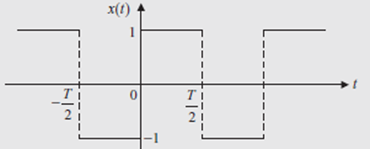  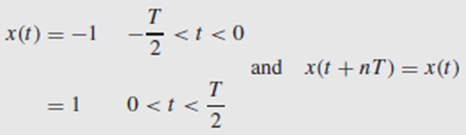

The answer is an = 0, bn  , as is derived at page 35.

This is plotted as follows.

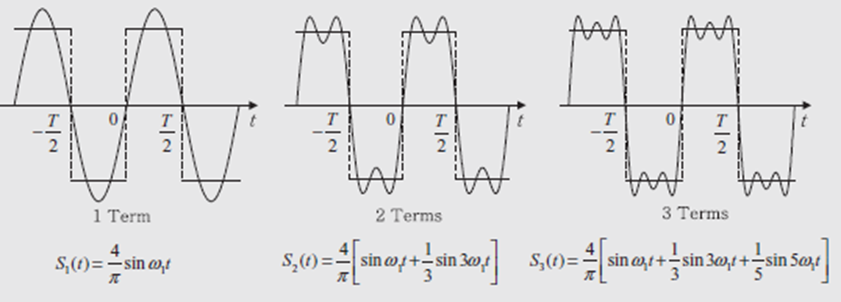

The coefficient bn is plotted as follows.

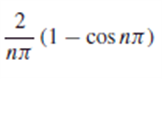 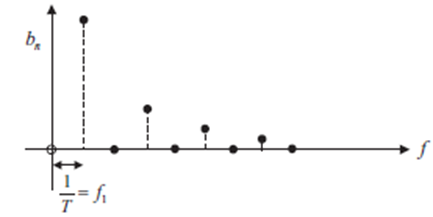

## 3.4 Complex form of Fourier series

The above representation

 or 

 can be stated differently as

  

For more detail, refer page 42.

In this equation, 

- there exist negative frequency, i.e., n extends from -inf to +inf.

- cn is complex. exp(j nt) is also complex. But adding two at n and -n, imaginary part cancels.

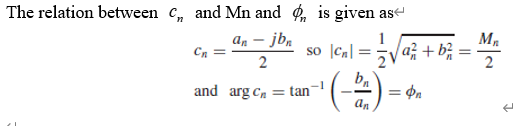

## 3.5 Spectra

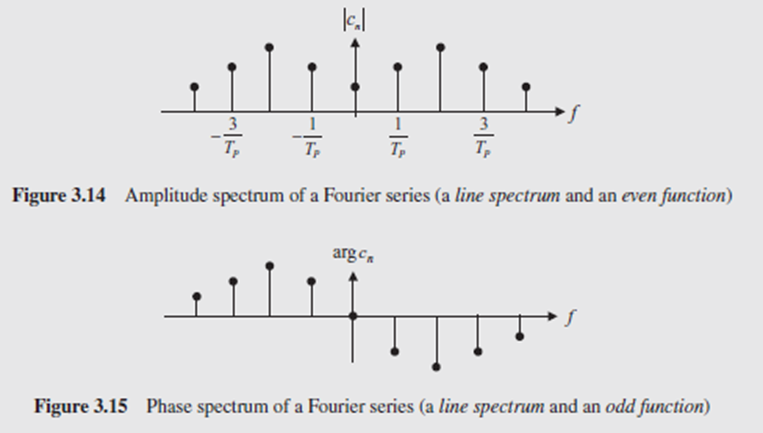

If we don't want negative part, we can plot  $M_n ,\phi_n$ versus  $n$ only.

We define average power as the sum square of cn,which means that avergave power of the signal x(t) is the sum of power of individual frequency components.

This has a ‘physical’ interpretation. It indicates that the average power of the signal x(t) may be regarded as the sum of power associated with individual frequency components.

The power spectrum is defined as ${{\left|c_n \right|}}^2$in the frequence domain.

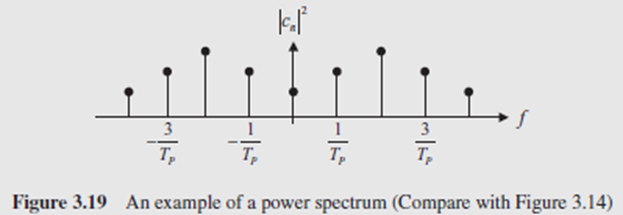

If we wish positive freq only, remove the left portion and double the values on the right.

#### Example: Fourier coefficient of even square wave. Let’s plot it.

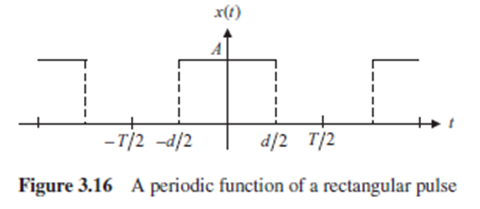

Result of Fourier coefficients are only the real an. No imaginary part bn. Therefore, arg(cn) is also zero.

When Tp=2, d=Tp/5, we have

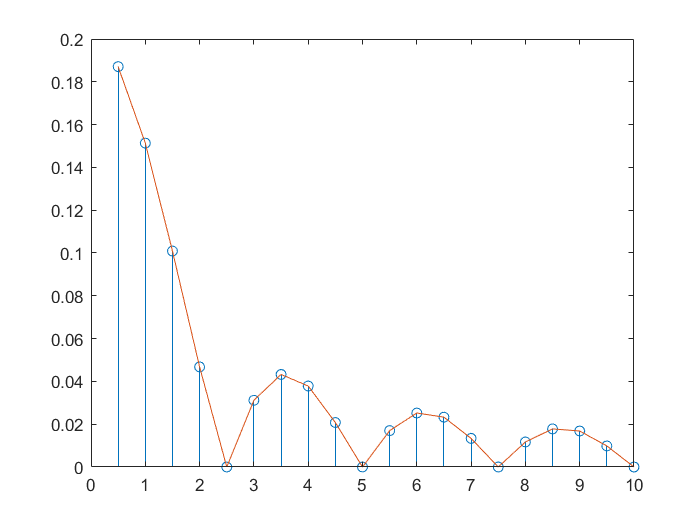

n=0:20; Tp=2; d=Tp/5; fn=n/Tp; cn=1/pi./n.*sin(pi*d*n/Tp); cn=abs(cn); 
figure; stem(fn,cn); hold on; plot(fn,cn); hold off

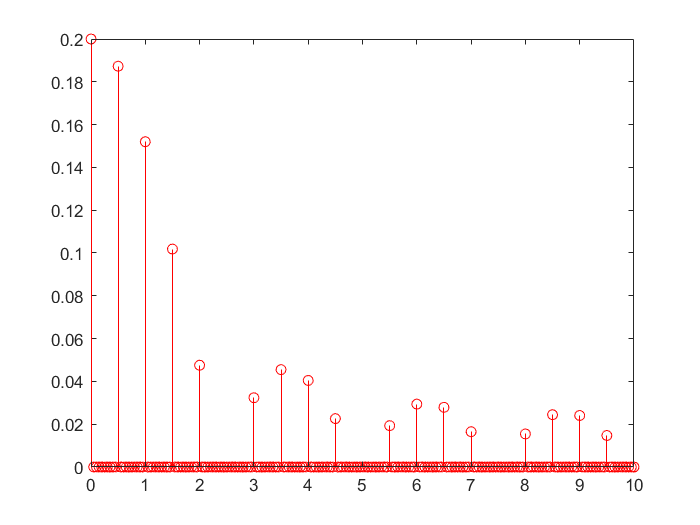


fs=20; Tp=2; d=Tp/5; r=10; T=r*Tp; t=0:1/fs:T-1/fs;
clear x; x=[ones(1,fs*d/2) zeros(1,fs*(Tp-d)) ones(1,fs*d/2)]; 
x=repmat(x,1,r);
N=length(x); X=fft(x); f=fs*(0:N-1)/N; 
figure; stem(f(1:N/2+1), abs(X(1:N/2+1)/fs/T), 'r'); 

Notes from the figure:

**The magnitude of Fourier coefficients cn are the half of the original coefficients Mn. **

**The Fourier series coefficients cn are the same as those of the FFT.**

**The max freq. in the FFT is half of the sampling rate fs. **

Example – odd square wave

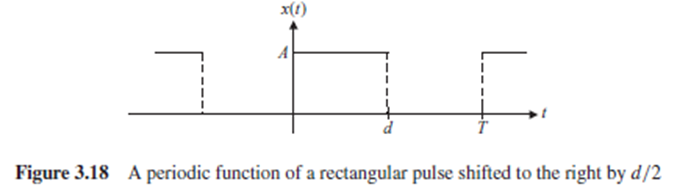

Then the answer is abs(cn) unchanged. But arg is -$n\pi \left(d/T\right)$                  .

## 3.6 Effect of time window

#### [Next Chapter >](matlab:open('./Ch_4.mlx'))

#### [Return Overview >](matlab:open('./PHM_Overview.mlx'))